#### Phase 1 & Phase 2: Analysis

Parameters

Adding matlab path to: D:\code\NN_molecular_communications\Section_IV_BioComputing\COMSOL_Three_Pipes
r_sensor=2 mm
Q_inlet_CNN=5 uL/min
height_pipe=36 um
c_Tartrazine_exp=0.08455 mol/L


c_max = 1

c_inlet=0.001 mol/L


mu = 9.9792e-04

D_coeff=4.9e-10 m^2/s



time_delta=0.01

time_delta = 0.0100

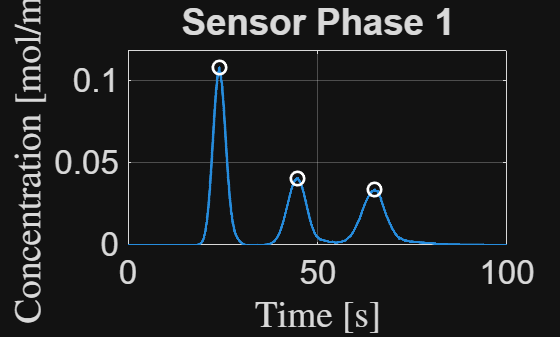


%Loading simulation results generated by COMSOL
% Specify the CSV file
csvFileName = 'c_CNN.csv';
%entry from the table
opts=detectImportOptions(csvFileName,'ReadVariableNames', false);
% preview(csvFileName,opts) %data file preview
Table_c_Pipe_CNN=readtable(csvFileName,opts);
t_COMSOL=(Table_c_Pipe_CNN.Var1);
c_COMSOL_Sensor_Phase_1=(Table_c_Pipe_CNN.Var2);
h_COMSOL_CNN_Phase_1=gradient(c_COMSOL_Sensor_Phase_1,t_COMSOL);

%finding the peaks
%First peak
[~,t_peak_A_COMSOL]=max(h_COMSOL_CNN_Phase_1);
t_peak_A_COMSOL=t_peak_A_COMSOL*time_delta;
%Second peak
[~,t_peak_B_COMSOL]=max(h_COMSOL_CNN_Phase_1((t_peak_A_COMSOL+tau_sample)/time_delta:end));
t_peak_B_COMSOL=t_peak_B_COMSOL*time_delta+t_peak_A_COMSOL+tau_sample;
%Third peak
[~,t_peak_C_COMSOL]=max(h_COMSOL_CNN_Phase_1(round((t_peak_B_COMSOL+tau_sample)/time_delta:end)));
t_peak_C_COMSOL=t_peak_C_COMSOL*time_delta+t_peak_B_COMSOL+tau_sample;

t=0:time_delta:time_simul;
figure;
% % plot(time,h_cir_1_Theo,'LineWidth',2); grid on; hold on;
plot(t_COMSOL,h_COMSOL_CNN_Phase_1,'LineWidth',2,'MarkerIndices',1:ceil(length(h_COMSOL_CNN_Phase_1)/15):length(h_COMSOL_CNN_Phase_1)); grid on; hold on;
plot(t_peak_A_COMSOL,h_COMSOL_CNN_Phase_1(round(t_peak_A_COMSOL/time_delta)),'ow','LineWidth',2,'MarkerSize',10); grid on; hold on;
plot(t_peak_B_COMSOL,h_COMSOL_CNN_Phase_1(round(t_peak_B_COMSOL/time_delta)),'ow','LineWidth',2,'MarkerSize',10); grid on; hold on;
plot(t_peak_C_COMSOL,h_COMSOL_CNN_Phase_1(round(t_peak_C_COMSOL/time_delta)),'ow','LineWidth',2,'MarkerSize',10); grid on; hold on;

xlabel('Time [s]','Interpreter','latex');
ylabel('Concentration [mol/m$^3$]','Interpreter','latex');
set(gca,'FontSize',fontsize);
title('Sensor Phase 1')
axis([0 t(end) 0 1.1*max(h_COMSOL_CNN_Phase_1)]);

% legend({'Theoretical results','Simulation in COMSOL','Peak approximation'},"Interpreter","latex")

#### Phase 2

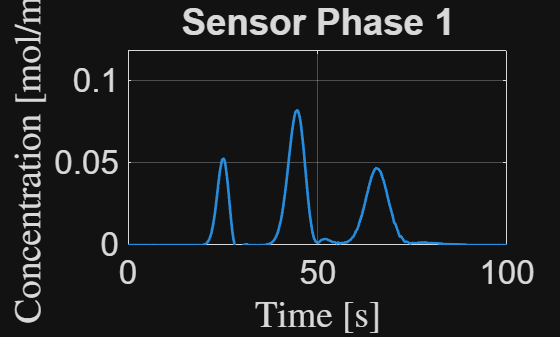

time_delta=0.1;

% Specify the CSV file
csvFileName = 'c_CNN_Outlet_Phase_2.csv';
%entry from the table
opts=detectImportOptions(csvFileName,'ReadVariableNames', false);
% preview(csvFileName,opts) %data file preview
Table_c_Pipe_CNN=readtable(csvFileName,opts);
t_COMSOL_Phase_2=(Table_c_Pipe_CNN.Var1);
c_COMSOL_CNN_Phase_2=(Table_c_Pipe_CNN.Var3);
h_COMSOL_CNN_Phase_2=gradient(c_COMSOL_CNN_Phase_2,t_COMSOL_Phase_2);

t=0:time_delta:time_simul;
figure;
% % plot(time,h_cir_1_Theo,'LineWidth',2); grid on; hold on;
plot(t_COMSOL_Phase_2,h_COMSOL_CNN_Phase_2,'LineWidth',2,'MarkerIndices',1:ceil(length(h_COMSOL_CNN_Phase_2)/15):length(h_COMSOL_CNN_Phase_2)); grid on; hold on;
% plot(t_peak_A_COMSOL,h_COMSOL_CNN_Phase_2(round(t_peak_A_COMSOL/time_delta)),'ow','LineWidth',2,'MarkerSize',10); grid on; hold on;
% plot(t_peak_B_COMSOL,h_COMSOL_CNN_Phase_2(round(t_peak_B_COMSOL/time_delta)),'ow','LineWidth',2,'MarkerSize',10); grid on; hold on;
% plot(t_peak_C_COMSOL,h_COMSOL_CNN_Phase_2(round(t_peak_C_COMSOL/time_delta)),'ow','LineWidth',2,'MarkerSize',10); grid on; hold on;

xlabel('Time [s]','Interpreter','latex');
ylabel('Concentration [mol/m$^3$]','Interpreter','latex');
set(gca,'FontSize',fontsize);
title('Sensor Phase 1')
axis([0 t(end) 0 1.1*max(h_COMSOL_CNN_Phase_1)]);

#### Phase 2: Load

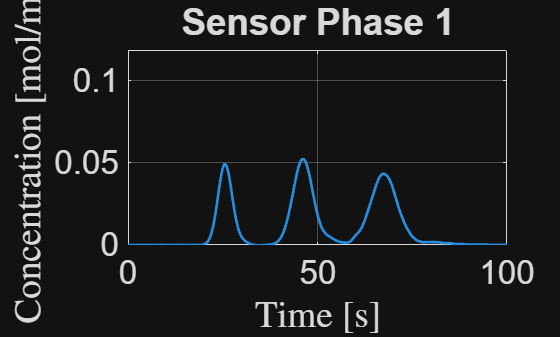

time_delta=0.1;

% Specify the CSV file
csvFileName = 'c_CNN_Phase_2_load.csv';
%entry from the table
opts=detectImportOptions(csvFileName,'ReadVariableNames', false);
% preview(csvFileName,opts) %data file preview
Table_c_Pipe_CNN=readtable(csvFileName,opts);
t_COMSOL_Phase_2=(Table_c_Pipe_CNN.Var1);
c_COMSOL_CNN_Phase_2=(Table_c_Pipe_CNN.Var4);
h_COMSOL_CNN_Phase_2=gradient(c_COMSOL_CNN_Phase_2,t_COMSOL_Phase_2);

t=0:time_delta:time_simul;
figure;
% % plot(time,h_cir_1_Theo,'LineWidth',2); grid on; hold on;
plot(t_COMSOL_Phase_2,h_COMSOL_CNN_Phase_2,'LineWidth',2,'MarkerIndices',1:ceil(length(h_COMSOL_CNN_Phase_2)/15):length(h_COMSOL_CNN_Phase_2)); grid on; hold on;
% plot(t_peak_A_COMSOL,h_COMSOL_CNN_Phase_2(round(t_peak_A_COMSOL/time_delta)),'ow','LineWidth',2,'MarkerSize',10); grid on; hold on;
% plot(t_peak_B_COMSOL,h_COMSOL_CNN_Phase_2(round(t_peak_B_COMSOL/time_delta)),'ow','LineWidth',2,'MarkerSize',10); grid on; hold on;
% plot(t_peak_C_COMSOL,h_COMSOL_CNN_Phase_2(round(t_peak_C_COMSOL/time_delta)),'ow','LineWidth',2,'MarkerSize',10); grid on; hold on;

xlabel('Time [s]','Interpreter','latex');
ylabel('Concentration [mol/m$^3$]','Interpreter','latex');
set(gca,'FontSize',fontsize);
title('Sensor Phase 1')
axis([0 t(end) 0 1.1*max(h_COMSOL_CNN_Phase_1)]);